# Modelos biomecánicos

# Humanoides

## Descripción del modelo Humanoide de Simulink

### Humanoide sujeto por la cintura

- El robot humanoide se base en un robot con dos brazos (4 DOF), dos piernas (4 DOF) y una cabeza (2 DOF)

- El humanoide puede estar agarrado por la cintura con lo que el modelo es estable, pudiendo mover los brazos y las piernas de forma independiente. Sería una simulación de un humanoide flotando, por ejemplo.

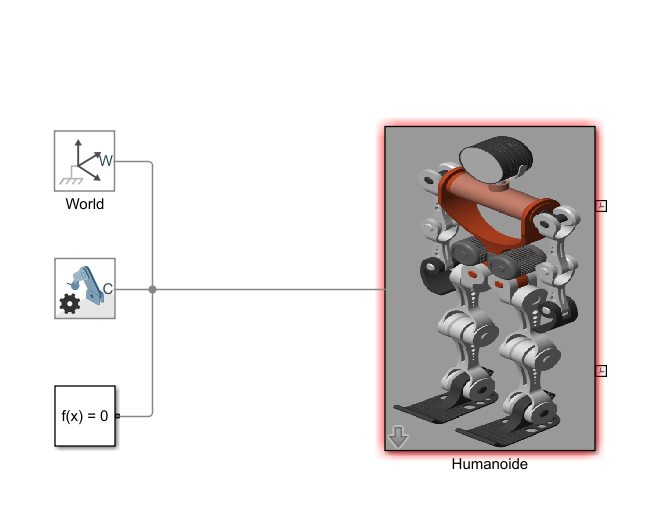

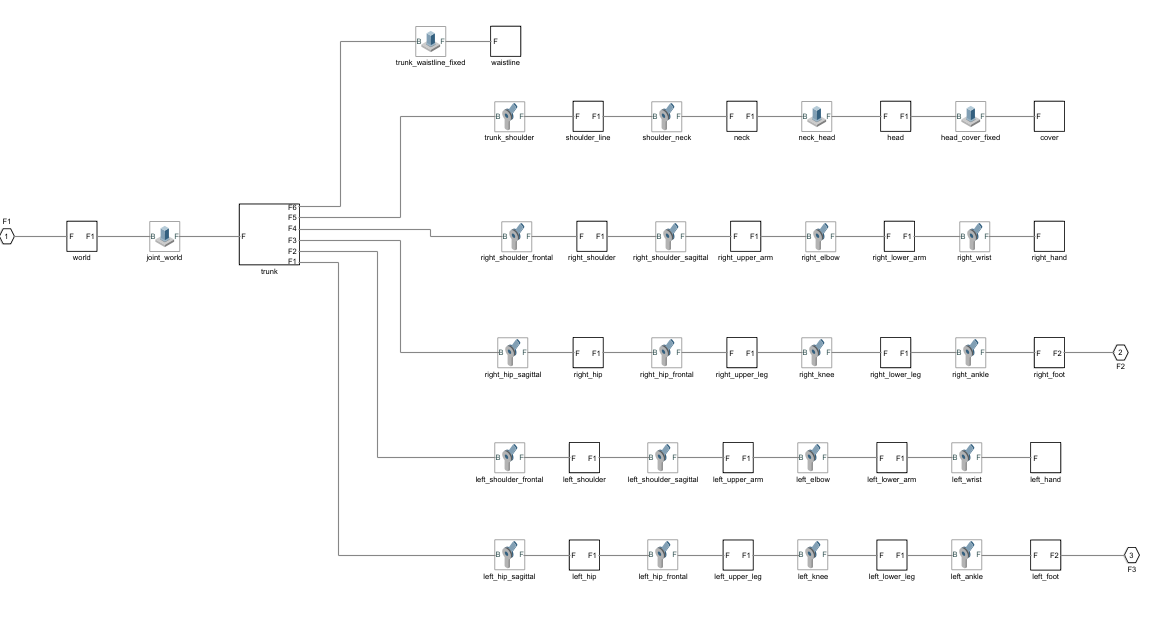

Estacion= 'H05S1_Humanoide';
deg= pi/180;
% Punto inicial de movimiento y base del robot
q0_= zeros(1,8)*deg;
% Se ha girado el robot para simular que nada
baseRobot_= [[0,0,0]*1e-3,[0,0,90]*deg];

open_system(Estacion)
sim(Estacion,1);

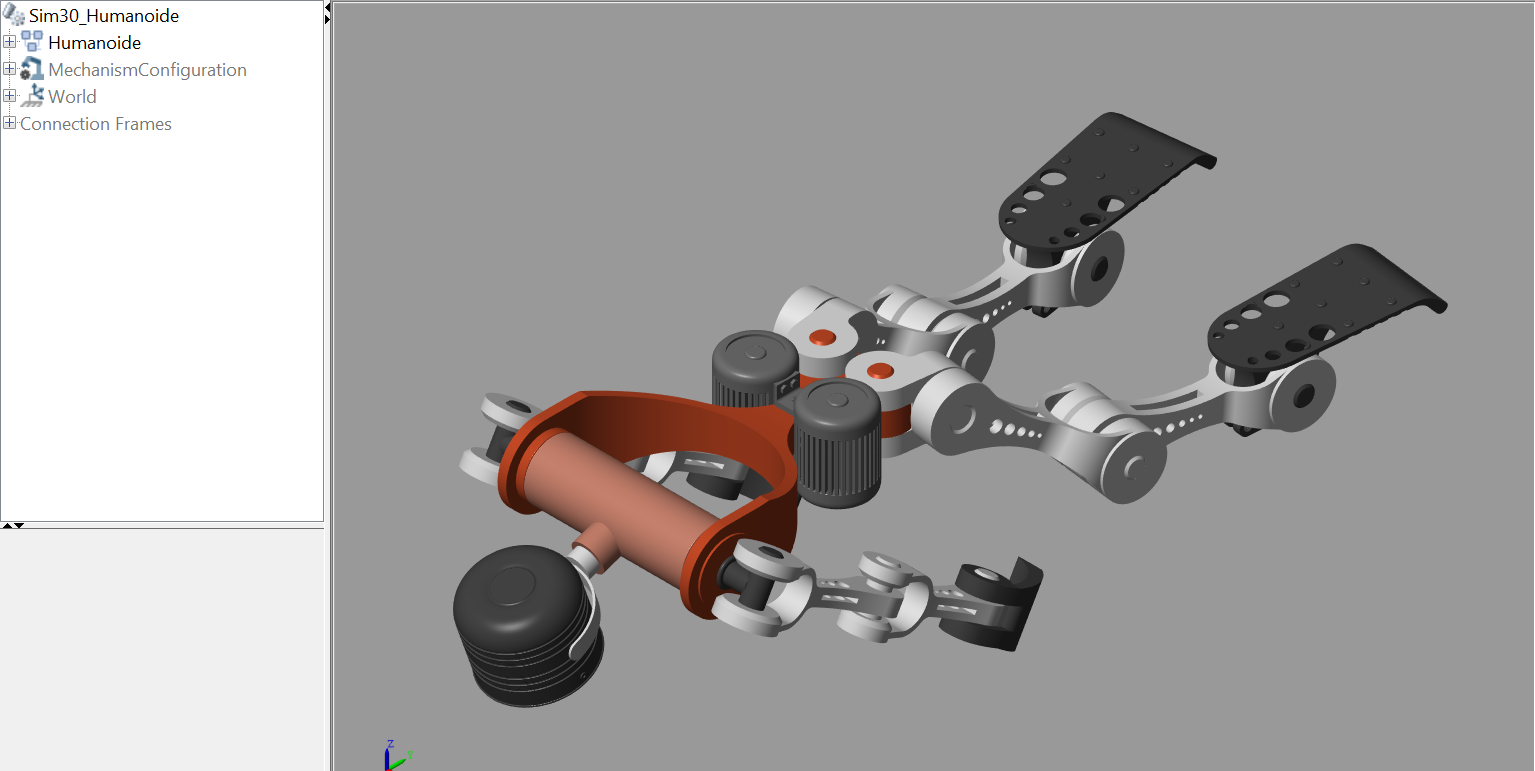

robot= importrobot(Estacion);
robot.showdetails

--------------------
Robot: (22 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  Body06(6)  Body10(10)  Body14(14)  Body18(18)  Body22(22)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   
   6        Body06        Joint06       revolute            Body01(1)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   Body08(8)  
   8        Body08        Joint08       revolute            Body07(7)   Body09(9)  
   9        Body09        Joint09       revolute            B

robot.showdetails
Cabeza= 'Body23';
PieD= 'Body10';
PieI= 'Body19';
ManoD= 'Body05';
ManoI= 'Body14';


### Humanoide de pie

- El humanoide puede estar sujeto por los pies, cuando estos están apoyados sobre una superficie, suelo. Sin fuerza en sus articulaciones, el humanoide se cae por efecto de la gravedad, pero sus pies se quedan pegados al suelo. 

- Para simular ese efecto se crean una esferas de radio pequeño a lo largo de los pies del humanoide y se "pega" con una determinada fuerza a la superficie (suelo), cuando están en contacto con ella.

- Se puede simular el  movimiento al andar de un humanoide con este sistema.

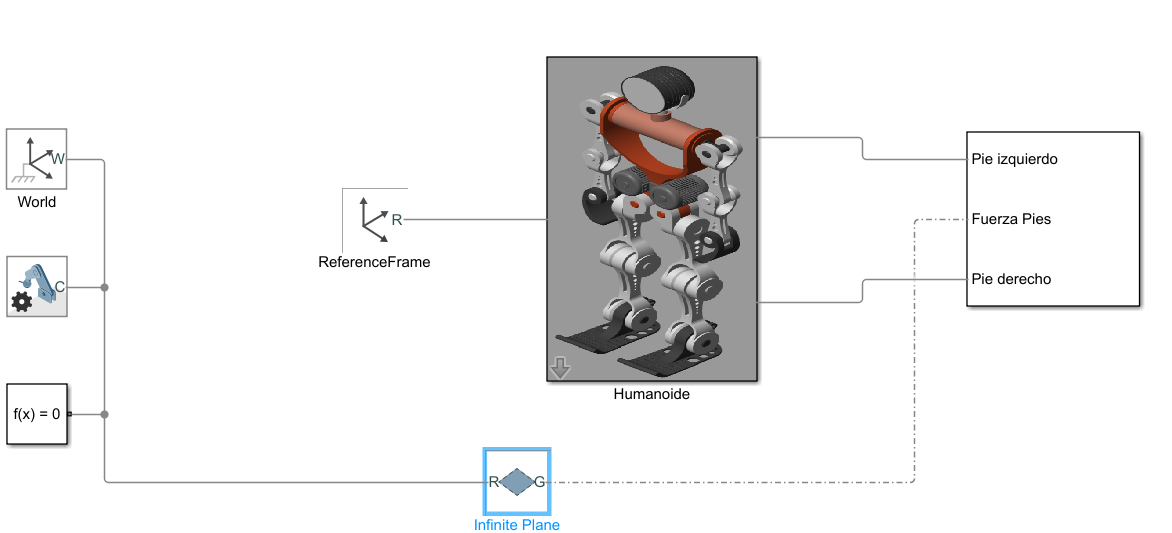

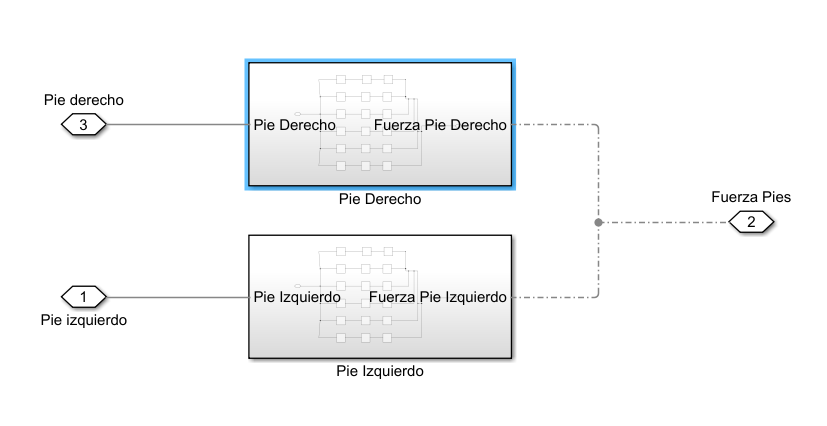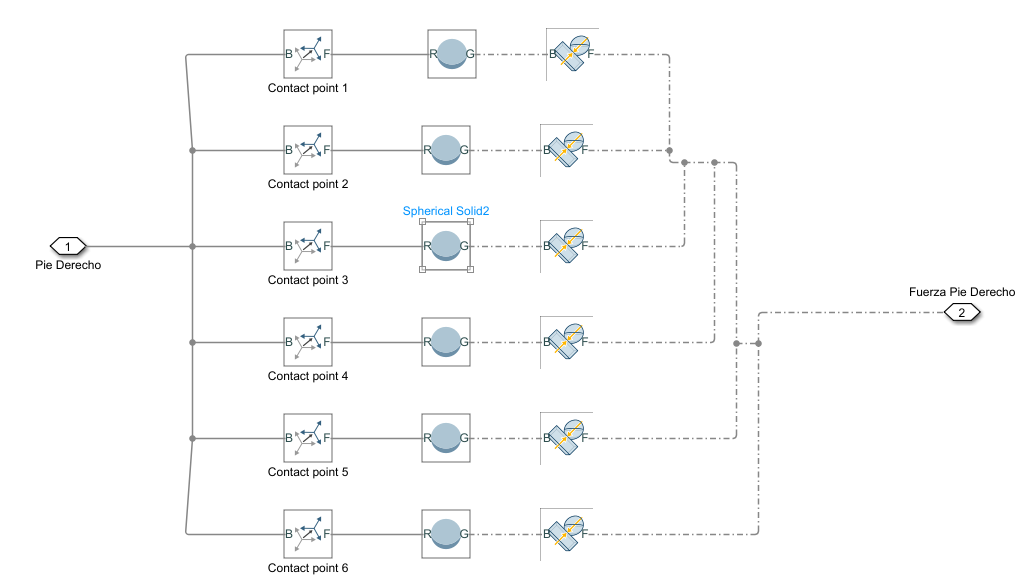

Estacion= 'H05S1_Humanoide_DePie';
deg= pi/180;
% Punto inicial de movimiento y base del robot
q0_= zeros(1,8)*deg;
% Se ha girado el robot para simular que nada
baseRobot_= [[0,0,440]*1e-3,[0,0,0]*deg];

open_system(Estacion)
sim(Estacion,1);

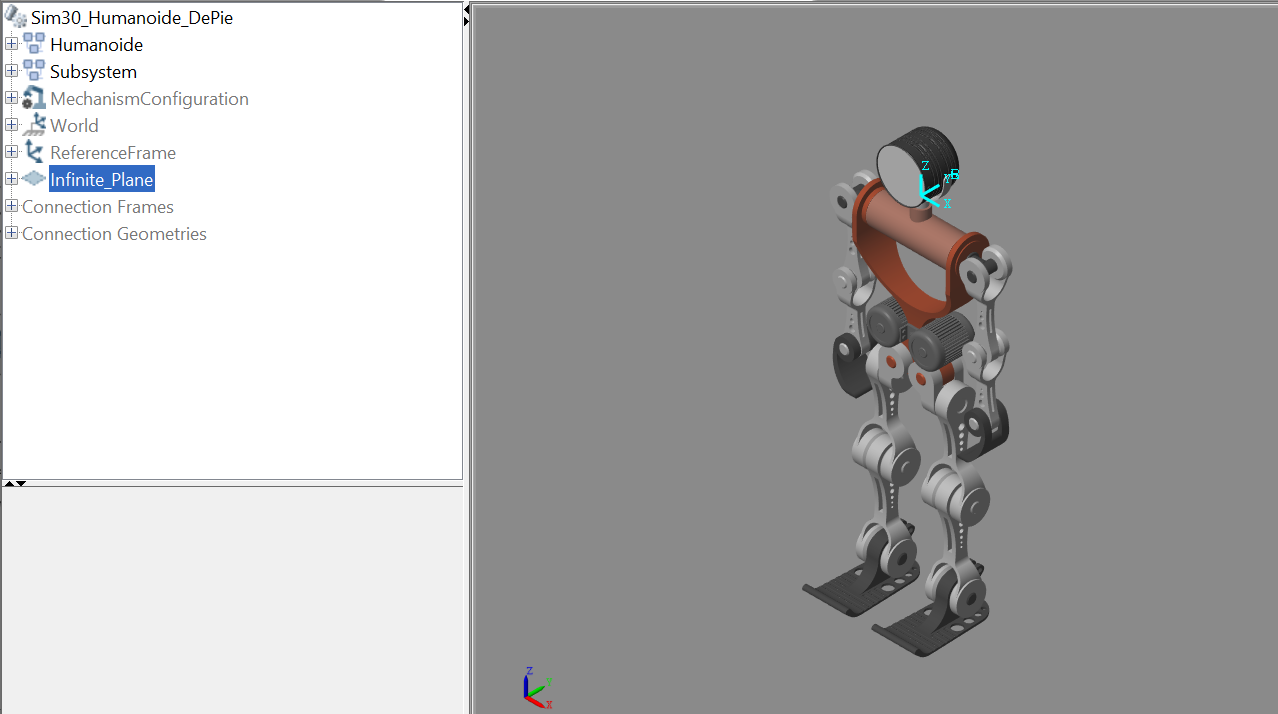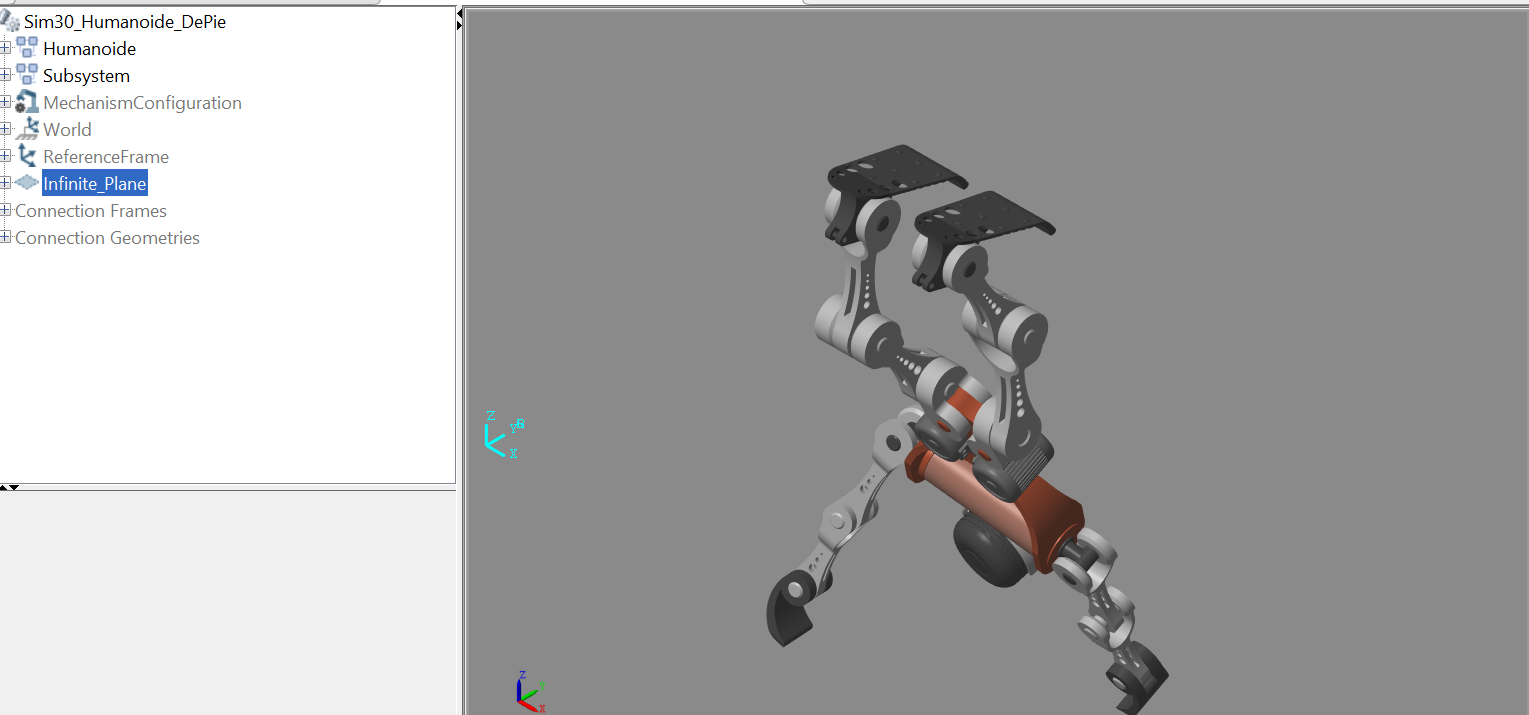



rob.MoveAbsJ()





## Humanoide con entrada posición, cintura fija

- Es un sistema en lazo cerrado, ya que la entrada es la referencia a la posición de cada eje. El robot calcula el torque que debe aplicar.

- Funciona como cuatro articulaciones separadas, cada una con 4 DOF.

- Se puede exportar a *RigidBody* y calcular las cinemáticas inversas.

- Dependiendo de que herramienta se use, manos o pies, el robot mueve en la cinemática inversa un brazo o pie.

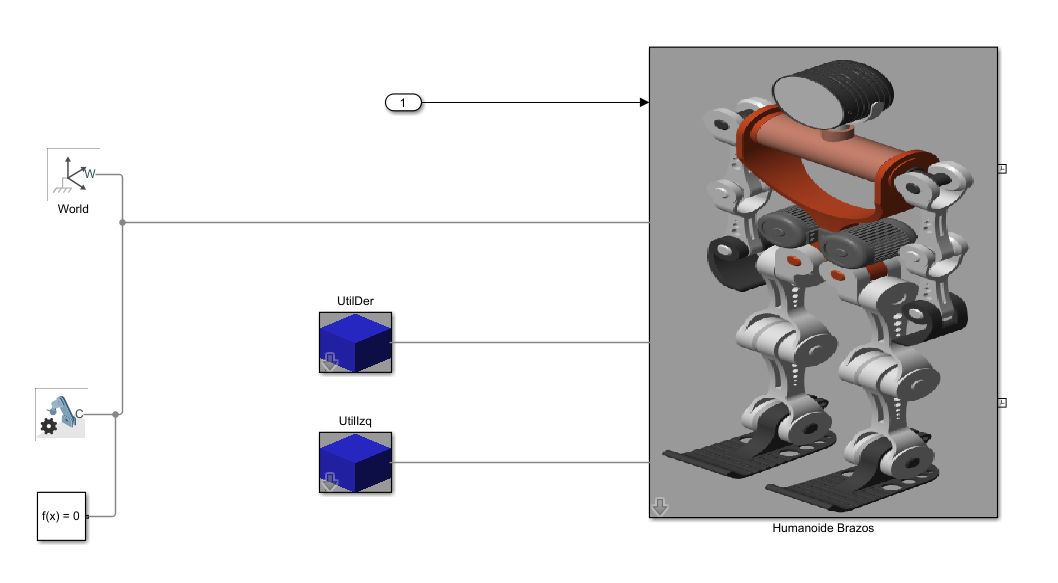

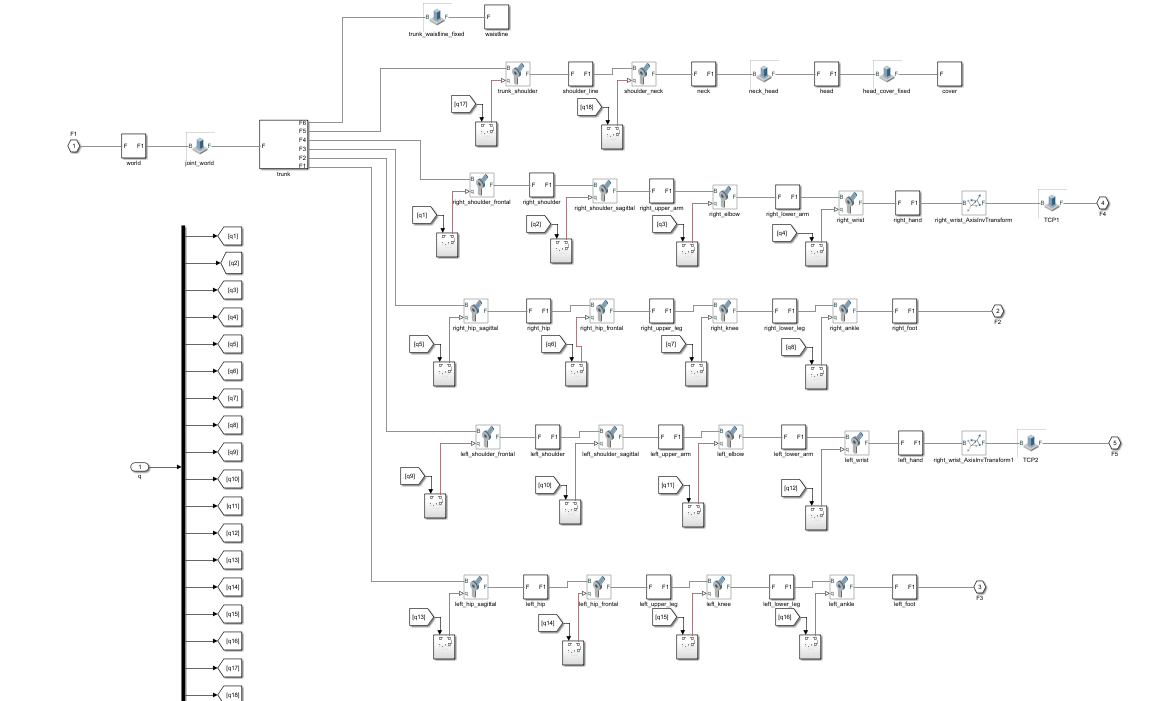

deg= pi/180;

% Variables internas de Cin
baseRobot= [[0,0,440]*1e-3,[0,0,0]*deg];
q0_= zeros(1,18);
pose_= randn(3,3)*1e-3;

Estacion= 'H05S2__Humanoide_Fijo_Cin';
%Estacion= 'Sim30_Humanoide_Libre';

%Pieza('UtilDer', 'Null');
% UtilDer.Base([[0, 0, 0]*1e-3, [0,0,0]*deg])
% UtilDer.Color([0,0.5,0,0.5]);

% Pieza('UtilIzq', 'Null');
% UtilIzq.Base([[0, 0, 0]*1e-3, [0,0,0]*deg])
% UtilIzq.Color([0.5,0,0,0.5]);

nPts= 1e4;
t= linspace(0, 5, nPts)';
q= linspace(0, 0*deg, nPts)';
Q= repmat(q,[1,18]);
open_system(Estacion)

Herramienta: Body05
Simulación. Ts= 0.100 m/s


rob = Herramienta: Body05
Modelo: H05S2__Humanoide_Fijo_Cin
Ts= 0.100 m/s
Entradas= 1-18
IK alg= W IK (pesos)

sim(Estacion,t,[],[t,Q]);

q0_= zeros(1,18);
q0= q0_;
rob= Cin(robot, Estacion, ManoD, q0)

q0= zeros(1,18);
rob.MoveAbsJ(q0);

theta= 60*deg;
q0(14)= theta;
q0(15)= -2*theta;
q0(16)= -theta;
q0(:,6)= -theta;
q0(:,7)= 2*theta;
q0(:,8)= -theta;



ans = 'Body14'

rob.MoveAbsJ(q0);

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0 

rob.Tool(ManoI)

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0 

rob.MoveAbsJ(zeros(1,18))
punto= [[10,10,10]*1e-3,[0,0,0]*deg];
rob.MoveJ(punto, rob)

## Importar el modelo para *RigidBody*

- Se importa el modelo y se da nombre a las articulaciones de los extremos de manos, pies y cabeza.

robot= importrobot(Estacion);

Error using robotics.SMImporter/processTranslationIssues
Unable to import rigidBodyTree from H05S2__Humanoide_Fijo_Cin. The model must contain a Simscape Multibody system.

Error in robotics.SMImporter/importrobot (line 175)
                obj.processTranslationIssues(modelName, translationData);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('importrobot', 'C:\Program Files\MATLAB\R2023a\toolbox\robotics\robotmanip\importrobot.m', 206)" style="font-weight:bo

robot.showdetails
Cabeza= 'Body23';
PieD= 'Body10';
PieI= 'Body19';
ManoD= 'Body05';
ManoI= 'Body14';


## Posible uso de Cin

- Se puede usar el objeto basado en *RigidBody* y la librería *Robotic Toolbox* para mover con cinemática inversa los brazos o piernas.

- Se va a mover una mano o pie de forma independiente una posición dada respecto de la original


% Crear objeto
q0= zeros(1,18);
rob= Cin(robot, Estacion, ManoD, q0);

Herramienta: Body23
Simulación. Ts= 0.100 m/s



PI= @(theta) -[-theta, 2*theta, theta, 0]*deg;
PD= @(theta) [-theta, 2*theta, -theta, 0]*deg;
iPI= 14:17;
iPD= 6:9;

q0= zeros(1,18);
rob.MoveAbsJ(q0);
theta= 30;
q0(iPI)= PI(theta);
q0(iPD)= PD(theta);

rob.MoveAbsJ(q0);



rob.MoveAbsJ(q0);
punto= [[0,0,-100]*1e-3,[0,0,0]*deg];

rob.MoveJ(punto, rob);

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0 

### Movimiento de una mano o pie


deg= pi/180;
q= zeros(1,18);
rob.Tool(ManoI);
%q(15)= -20*deg;
rob.MoveAbsJ(q);
q(9:12)= 30*deg;
rob.MoveAbsJ(q);


rob.Tool(ManoD);
pose= rob.Pose; % Posición tool
%pose= pose*1.2; % Modificación de posición
pose(1:3)= pose(1:3)*2; 
rob.MoveJ(pose); % Mover a posición modificada


## Humanoide con entrada posición, de pie

- El sistema realmente funciona en lazo cerrado, ya que la entrada es la posición y el robot calcula el par necesario para conseguirlo.

- No se puede poner restricciones en las articulaciones, ya que el robot ejerce un torque suficiente para cumplir el objetivo de posición.

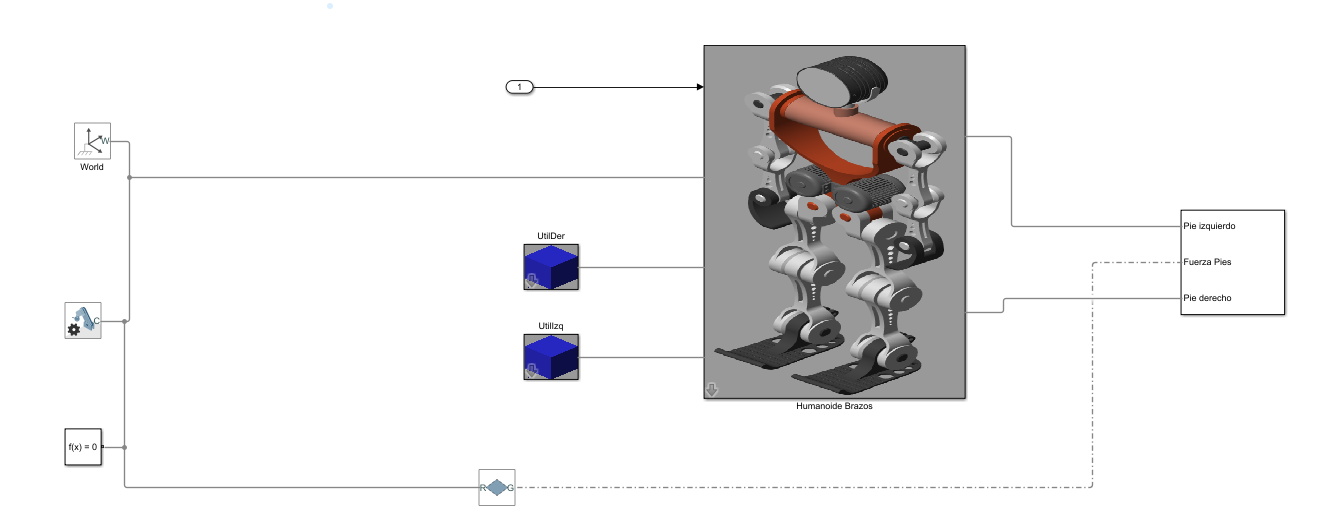

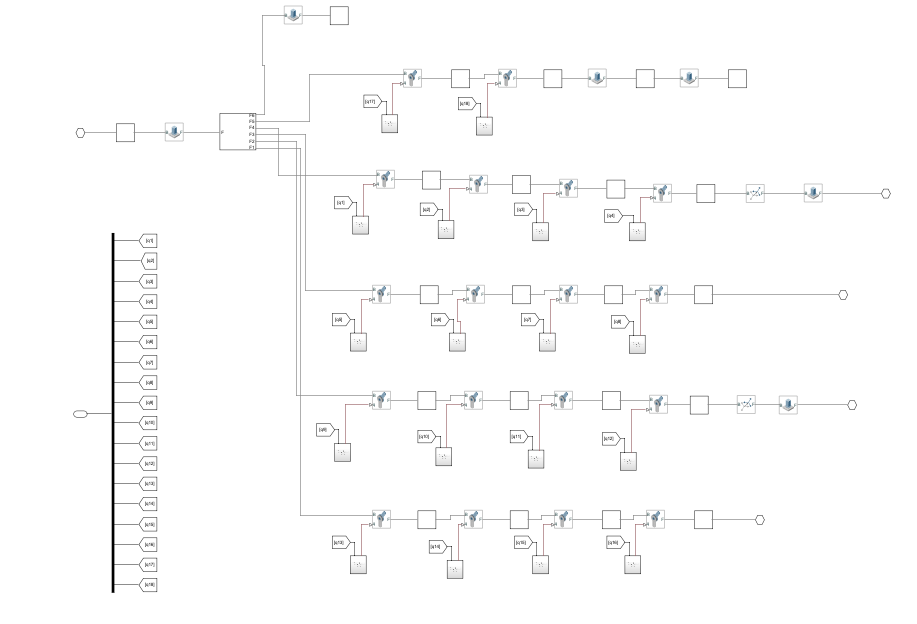

deg= pi/180;

% Variables internas de Kin
baseRobot= [[0,0,440]*1e-3,[0,0,0]*deg];
q0_= zeros(1,18);


Estacion= 'Sim40_Humanoide_FK_DePie';
%Estacion= 'Sim30_Humanoide_Libre';

UtilDer= Pieza('Null');
UtilDer.Base([[0, 0, 0]*1e-3, [0,0,0]*deg])
UtilDer.Color([0,0.5,0,1]);

UtilIzq= Pieza('Null');
UtilIzq.Base([[0, 0, 0]*1e-3, [0,0,0]*deg])
UtilIzq.Color([0.5,0,0,1]);

nPts= 1e4;
t= linspace(0, 25, nPts)';
q= linspace(0, 30*deg, nPts)';
Q= repmat(q,[1,18]);
open_system(Estacion)
sim(Estacion,t,[],[t,Q]);


## Humanoide con entrada en torque y realimentación, de pie

- Es el modelo más real de todos.

- El sistema es en lazo abierto, ya que su entrada es el torque de las articulaciones.

- El lazo se cierra con un controlador proporcional, que puede simular la capacidad del musculo para mover la articulación.

- En este caso sí se pueden poner restricciones en las articulaciones, ya que el torque que se puede dar en cada articulación está acotado.

- Se puede medir la posición de la cintura del robot, para poder realimentar el mismo en función de su estabilidad.

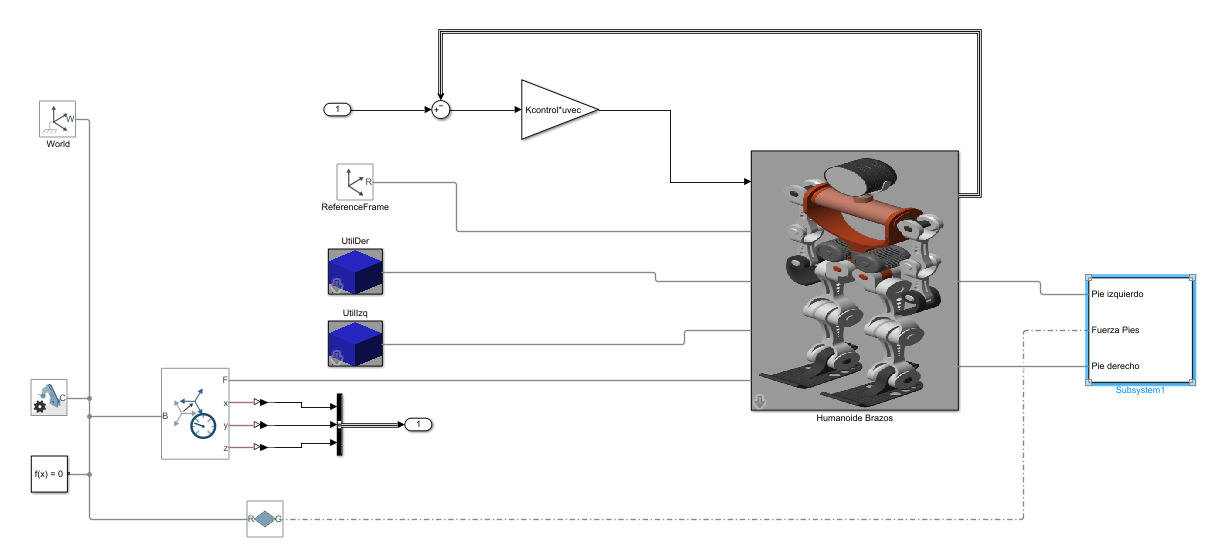

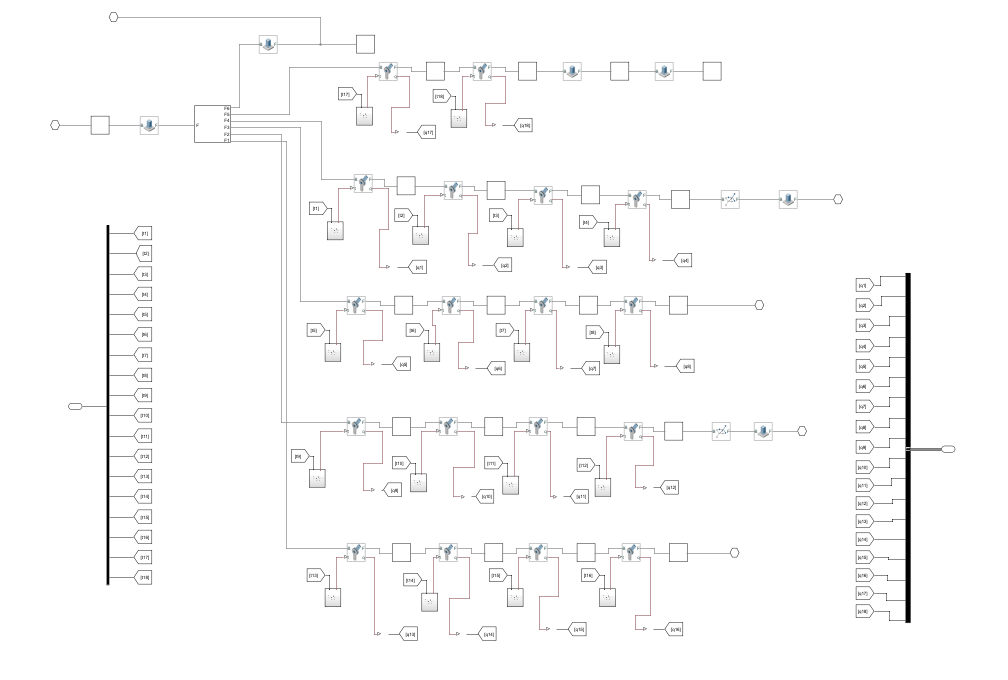

deg= pi/180;

% Variables internas de Kin
baseRobot= [[0,0,440]*1e-3,[0,0,0]*deg];
q0_= zeros(1,18);

% Controlador
Kq= diag(ones(1,18)*1e2);
Kw= diag(ones(1,18)*1e2);

Estacion= 'Sim40_Humanoide_Interno_DePie';
%Estacion= 'Sim30_Humanoide_Libre';

UtilDer= Pieza('Null');
UtilDer.Base([[0, 0, 0]*1e-3, [0,0,0]*deg])
UtilDer.Color([0,0.5,0,0.5]);

UtilIzq= Pieza('Null');
UtilIzq.Base([[0, 0, 0]*1e-3, [0,0,0]*deg])
UtilIzq.Color([0.5,0,0,0.5]);

nPts= 1e3;
t= linspace(0, 10, 2*nPts)';

q= linspace(0, 30*deg, nPts)';
Q1= zeros(nPts,18);
Q1(:,7)= q;
Q1(:,15)= -q;
Q1(:,8)= -q;
Q1(:,16)= -q;

Q2= zeros(nPts,18);
Q2(:,1)= q;

Q2(:,7)= Q1(end,7);
Q2(:,15)= Q1(end,15);
Q2(:,8)= Q1(end,8);
Q2(:,16)= Q1(end,16);
Q= [Q1;Q2];

%Q= repmat(q,[1,18]);
open_system(Estacion)
Q= zeros(2*nPts,18)

Q =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   

sol= sim(Estacion,t,[],[t,Q]);

x= sol.yout(:,1);
y= sol.yout(:,2);

Index in position 2 exceeds array bounds. Index must not exceed 1.

z= sol.yout(:,3);
tout= sol.tout;

plot(t, [x,y,z])



deg= pi/180;
% Variables internas de la estación Posición robot y q0 inicial
baseRobot= [[0,0,440]*1e-3,[0,0,0]*deg];
q0_= zeros(1,18);

% Controladores, control de posición y velocidad (elimina ruidos)
Kq= diag(ones(1,18)*1e2);
Kw= diag(ones(1,18)*1e2);
Estacion= 'Sim41_Humanoide_Interno_DePie';


UtilDer= Pieza('Dado');
UtilDer.Base([[0, 0, 0]*1e-3, [0,0,0]*deg])
UtilDer.Color([0,0.5,0,1]);

UtilIzq= Pieza('Dado');
UtilIzq.Base([[0, 0, 0]*1e-3, [0,0,0]*deg])
UtilIzq.Color([0.5,0,0,1]);

nPts= 1e2;
t= linspace(0,10,nPts)';

sim(Estacion, t, [], [t, repmat(q0_,[nPts,1])])

ans =   Simulink.SimulationOutput:

                   tout: [100x1 double] 
                   yout: [100x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Movimientos
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


H= Hum(Estacion, eje, baseRobot_, q0_);
tinc= 1;

paso= 30;


%  Mueve la cadera, rodillas de la pierna derecha y los dos brazos
joint1= [H.eje.CadIF, 60; H.eje.RodI, 60];%; H.eje.HomDF, 30, ; H.eje.HomIF, -30]; 
H.AddMove(joint1, tinc)
% Mueve la rodilla y tobillo de la pierna derecha
joint2= [H.eje.RodD, paso; H.eje.TobD, -paso];
H.AddMove(joint2, tinc)

% Pone la cadera y rodilla derecha en su posición inicial
joint3= [H.eje.CadIF, 0; H.eje.RodI, 0];
%joint3= [H.eje.CadIF, 0; H.eje.RodI, 0; H.eje.CadDF, 60];
H.AddMove(joint3, tinc)

% Pone la rodilla y tobillo derecho en su posición inicial
joint4= [H.eje.RodD, 0; H.eje.TobD, 0; H.eje.HomDF, 0];%; H.eje.HomIF, 0; H.eje.HomDF, 0];
H.AddMove(joint4, tinc)

% Simula
[t, pose]= H.Sim;


subplot(2,1,1)
plot(t,pose(:,1:3)*1e3); title('[x,y,z] (mm)')
subplot(2,1,2)
plot(t,pose(:,4:6)*180/pi); title('[Rz,Ry,Rx] (deg)')